# Εργαστήριο Ψηφιακής Επεξεργασίας Σημάτων

## Συμπλήρωμα Αναφοράς 4ης Εργαστηριακής Άσκησης.

#### Λουδάρος Ιωάννης - 1067400

Εδώ περιλαμβάνεται ο κώδικας που χρησιμοποιήθηκε για την εκπόνηση της Άσκησης.

clear;clc;close all

## Άσκηση 1 : Στοχαστικές Διαδικασίες 

### Υλοποίηση Στοχαστικής Διαδικασίας  

K = 1000;
n = -50:200;
A = rand(K,1) - 1/2;



mask = ((n > 0) - (n - 100 > 0));


x = A* mask ;% ones(length(mask),length(mask));

mask2D = repmat(mask,K,1);

x = A .* mask2D;
mean_val = mean(x);



### Υπολογισμός Αυτοσυσχέτισης και Πυκνότητας Φάσματος

Acor = x'*x/K;
Sd = 20*log10(fftshift(abs(fft2(Acor))));

### Γραφικές Παραστάσεις

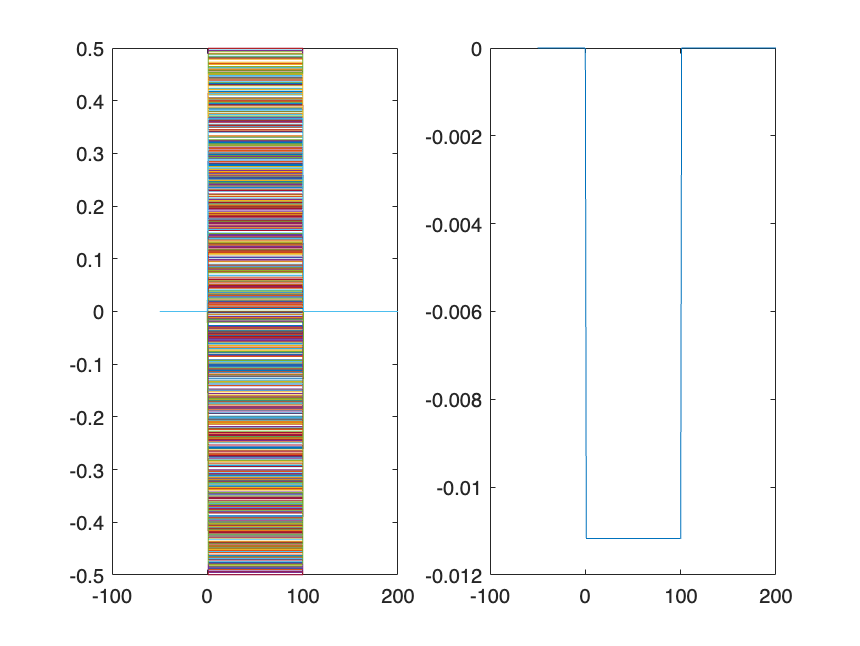

figure;
subplot(121);plot(n,x);
subplot(122);plot(n,mean_val);

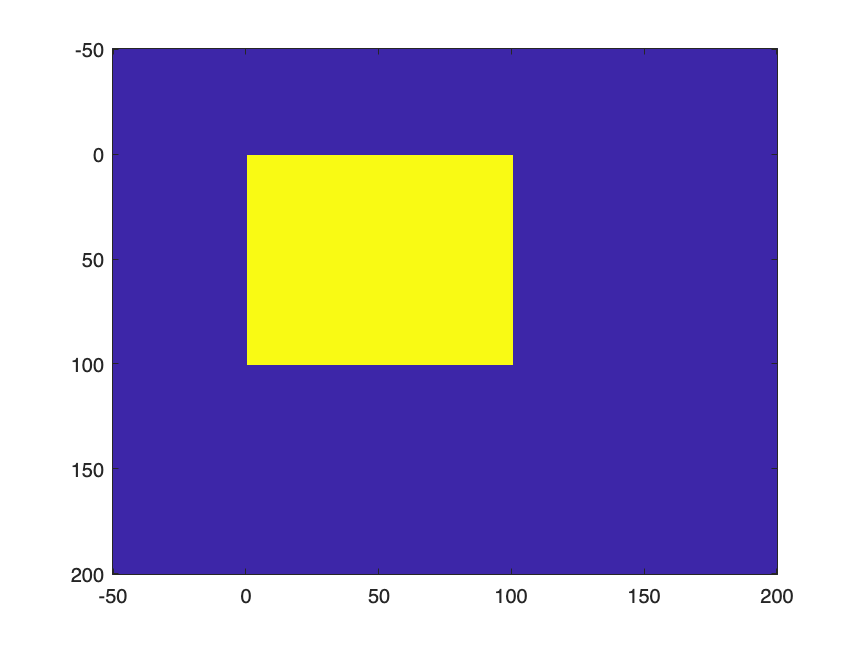




figure; imagesc(n,n,Acor)

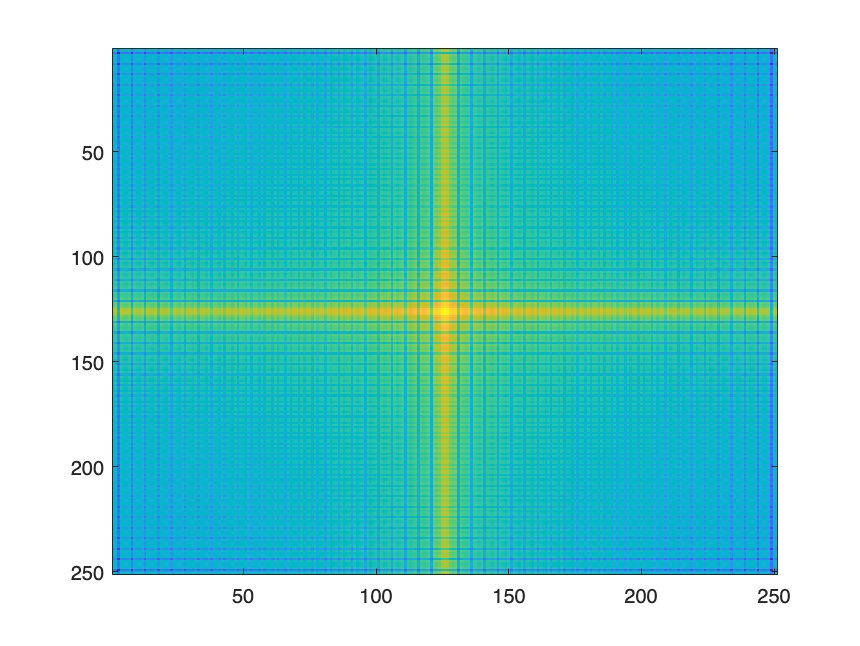


figure; imagesc(Sd)

## Άσκηση 2 : Στοχαστικές Διαδικασίες 

### Υλοποίηση Στοχαστικής Διαδικασίας

K = 1000;
n = -50:200;
A = randn(K,1);



mask = ((n > 0) - (n - 100 > 0));


x = A* mask ;% ones(length(mask),length(mask));

mask2D = repmat(mask,K,1);

x = A .* mask2D;
mean_val = mean(x);



### Υπολογισμός Αυτοσυσχέτισης και Πυκνότητας Φάσματος

Acor = x'*x/K;
Sd = 20*log10(fftshift(abs(fft2(Acor))));

### Γραφικές Παραστάσεις

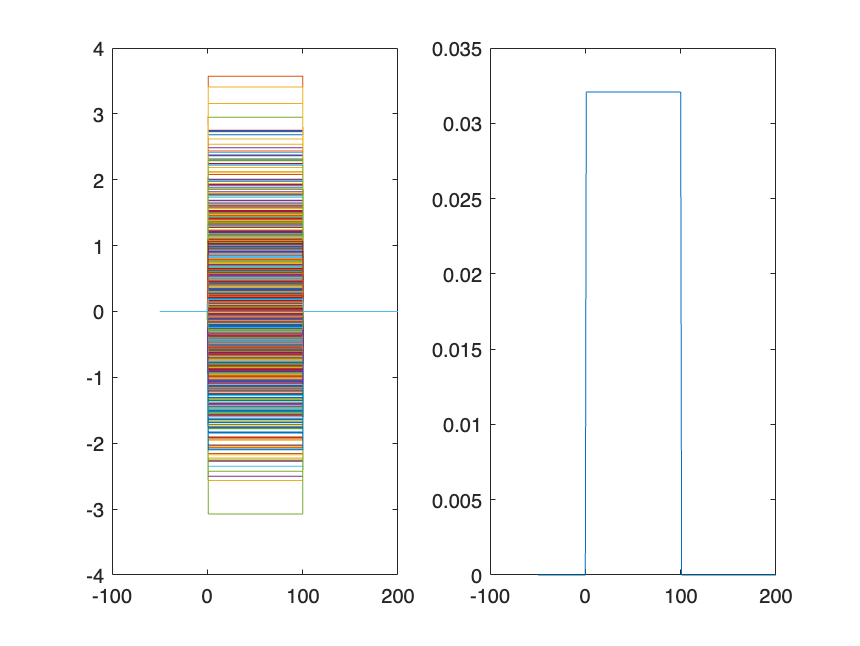

figure;
subplot(121);plot(n,x);
subplot(122);plot(n,mean_val);




figure; imagesc(n,n,Acor)


figure; imagesc(Sd)

## Άσκηση 3 : Βασικοί Νόμοι της Στατιστικής

### Αποθορυβοποίηση μέσω του Νόμου των Μεγάλων Αριθμών

load eye

#### Εφαρμογή του Νόμου των Μεγάλων Αριθμών

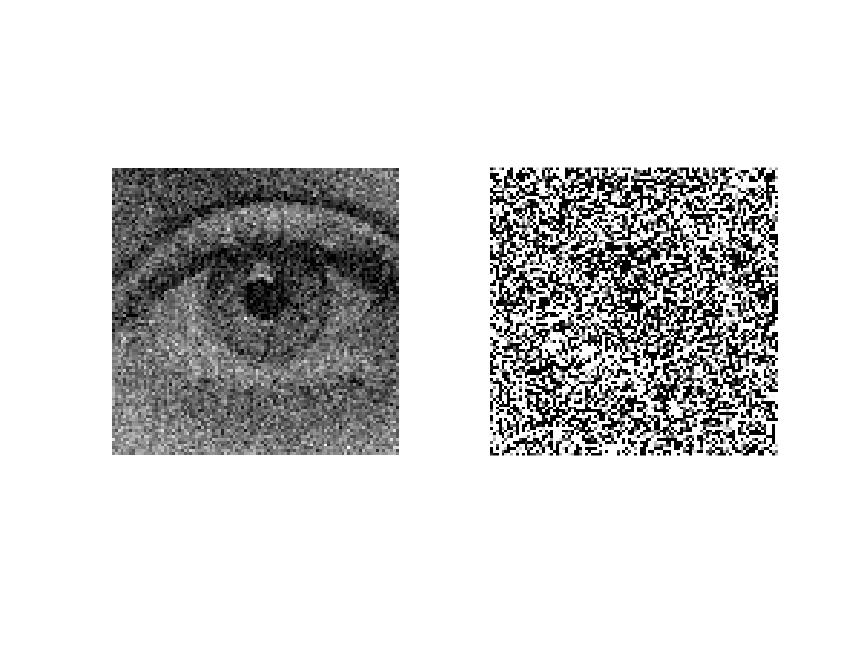

approx = zeros(size(I(:,:,1)));

for counter = 1 : 100
    approx = approx + I(:, :, counter);
end

approx = approx/100;

figure;
subplot(121);imshow(approx/max(approx(:)));
subplot(122);imshow(I(:,:,1))

### Κεντρικό Οριακό Θεώρημα

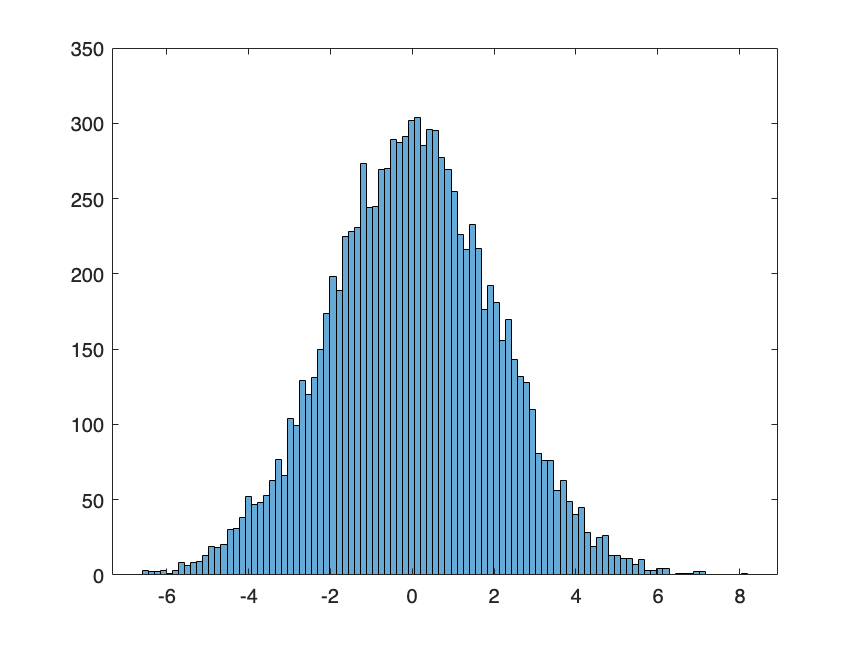

%for a single image
noise = I(:,:,1) - approx;
figure;
histogram(noise, 100);

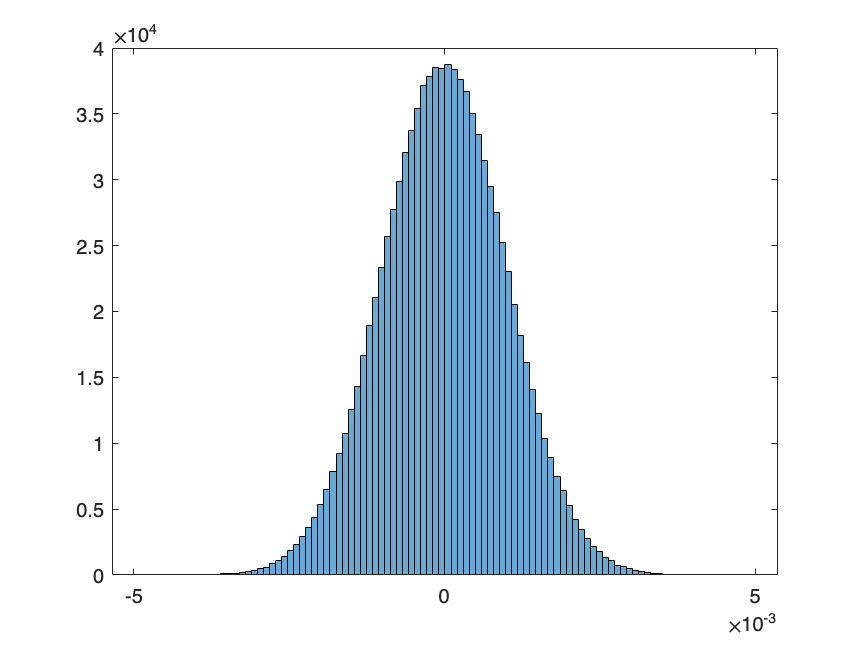




m = mean(noise(:));
s = std(noise(:));

I2 = zeros(size(I(:,:,1)));
for counter = 1 : 100
    I2 =  I2 + I(:, :, counter) -  approx;
end

%divide by sigma
I2 = I2/(10*s);


m=mean(I(:)); %flatten I to a vector by I(:)
s = std(I(:));

figure;
samples = (I(:)-m)/(s*sqrt(100^3));
histogram(samples, 100); %should be gaussian N(0,1)

#### Ανάλυση Θορύβου

variance = mean(var(noise))

variance = 4.0500

## Άσκηση 4 : FIR Φίλτρο Wiener

### Σχεδίαση και Εφαρμογή Φίλτρου 

#### Φίλτρο Μήκους 2

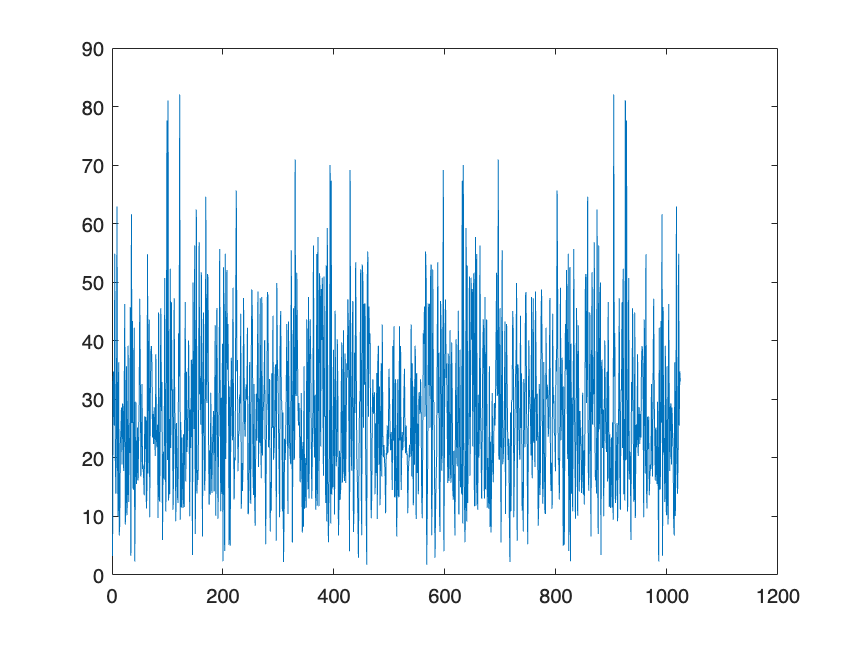

n=0:1000;
phi = rand(1)*2*pi;
s = sin(0.25*n+phi);

w = randn(1,length(n));
v = filter(1,[1,-0.6],w); %colored noise

%check 
figure;plot(abs(fftshift(fft(w,2^10))))

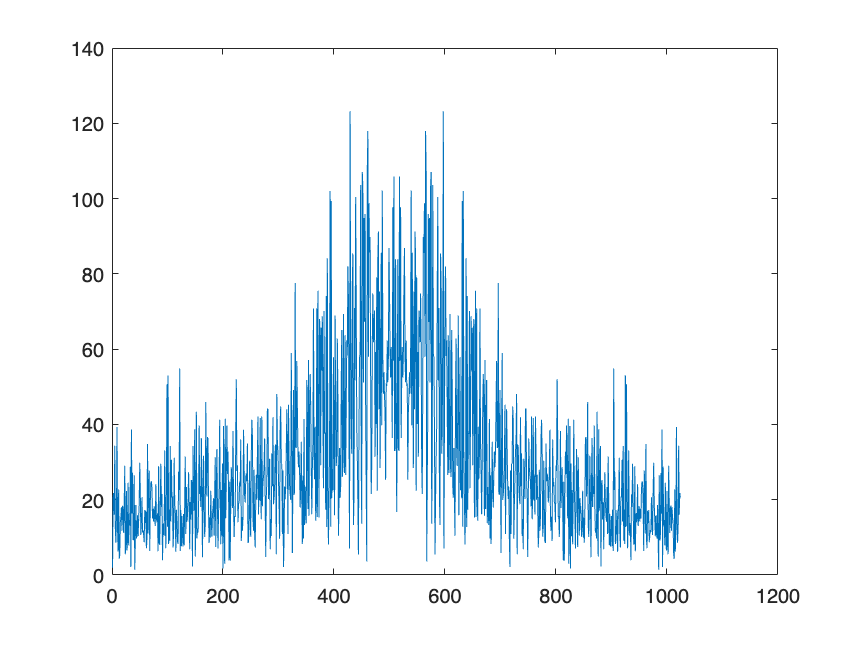


figure;plot(abs(fftshift(fft(v,2^10))))

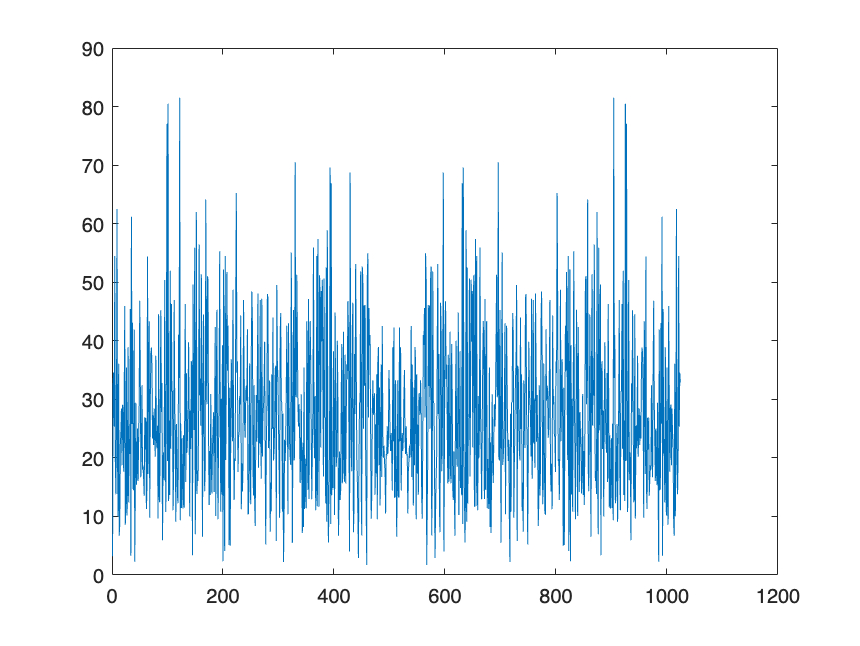


x = s+w;


%rn = w.*v;
v0 = v;
w0 = w;

%find the cross correlation
rsx=[0;0];
for n=6:length(v)
    rsx(1)=rsx(1)+v(n)*w(n);
    rsx(2)=rsx(2)+v(n-1)*w(n);
end
rsx=rsx/(length(v)-1);


%find the autocorrelation
v1 = v0;
v2 = v0;

v1(end) = [];
v2(1) = [];

X = [v2;v1];
Rxx = X*X'/length(v1);


hW =  rsx' * inv(Rxx);

%hW = hW;

%corr_vector = xcorr(v, w);

%here find the filter hW
%hW =[];

%apply to colored noise to make it white again
w_hat = filter(hW,1,v);

%check to see the whitening
figure;plot(abs(fftshift(fft(w_hat,2^10))))

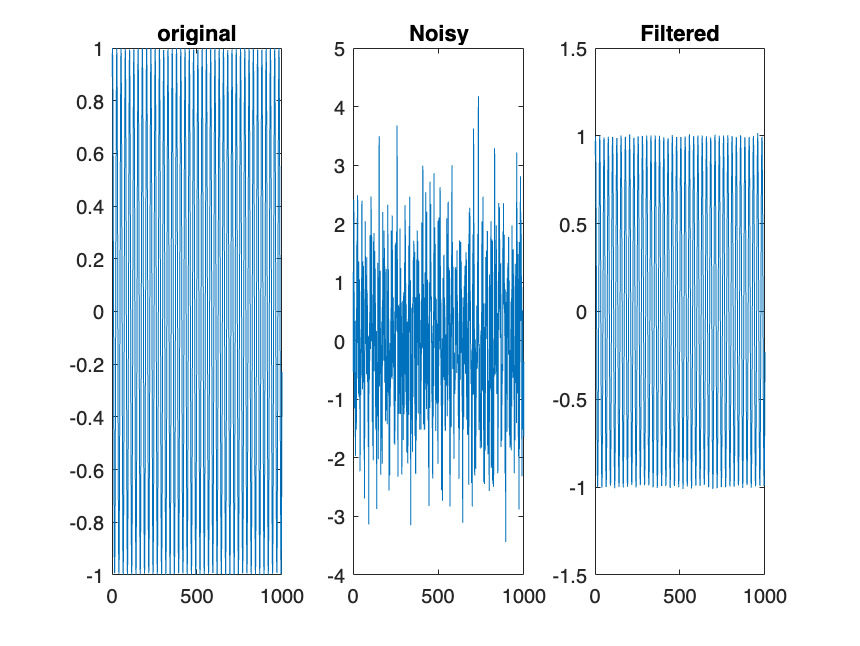



norm(w-w_hat); %to minimize
x_hat = x-w_hat;

subplot(131);plot(s);title('original');
subplot(132);plot(x);title('Noisy');
subplot(133);plot(x_hat);title('Filtered');



rms_noise_2 = norm(x-s)

rms_noise_2 = 31.0338

rms_filtered_noise_2 = norm(x-s-w_hat)

rms_filtered_noise_2 = 0.2062

#### Φίλτρο Μήκους 3

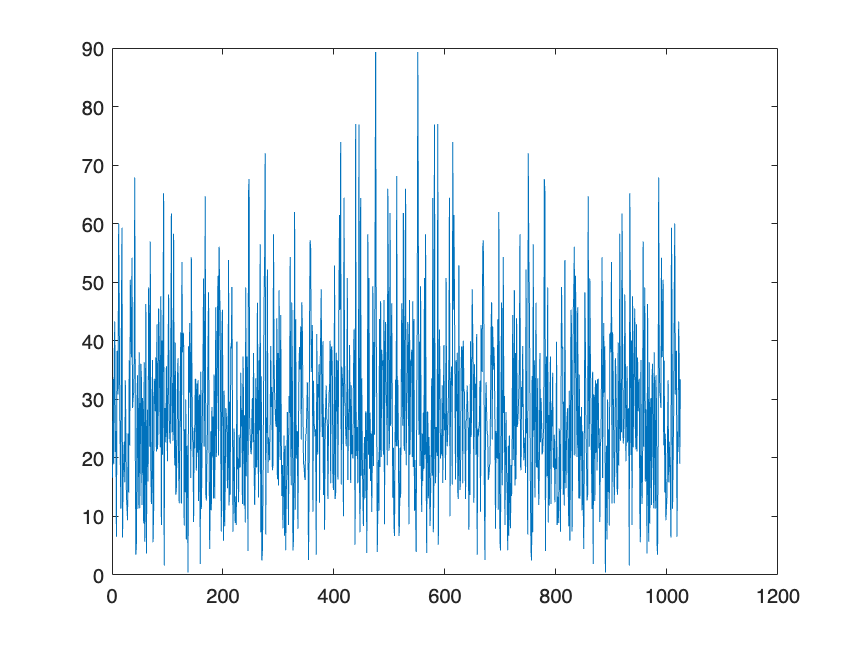

n = 0:1000;
phi = rand(1)*2*pi;
s = sin(0.25*n+phi);

w = randn(1,length(n));
v = filter(1,[1,-0.6],w); % colored noise

% check
figure; plot(abs(fftshift(fft(w,2^10))))

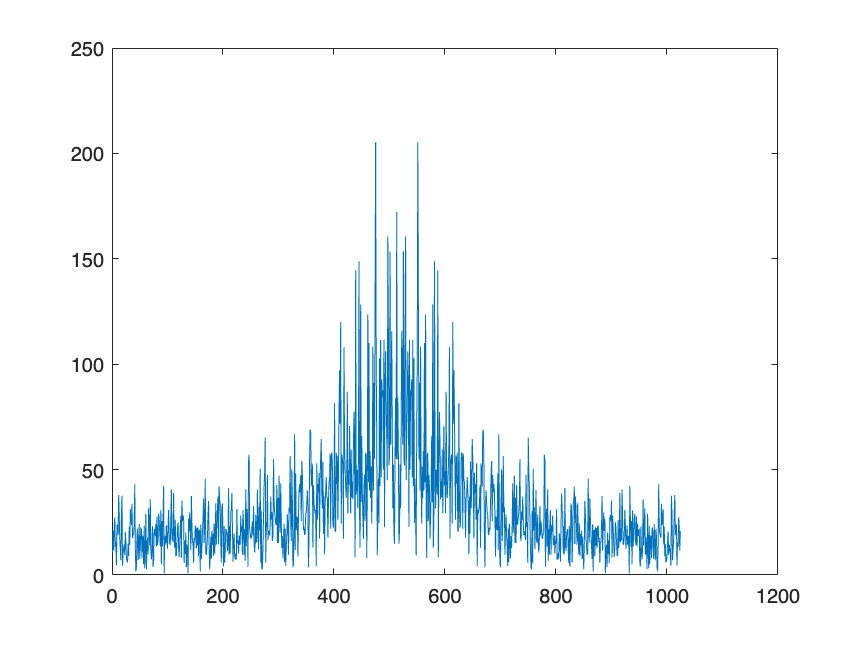

figure; plot(abs(fftshift(fft(v,2^10))))

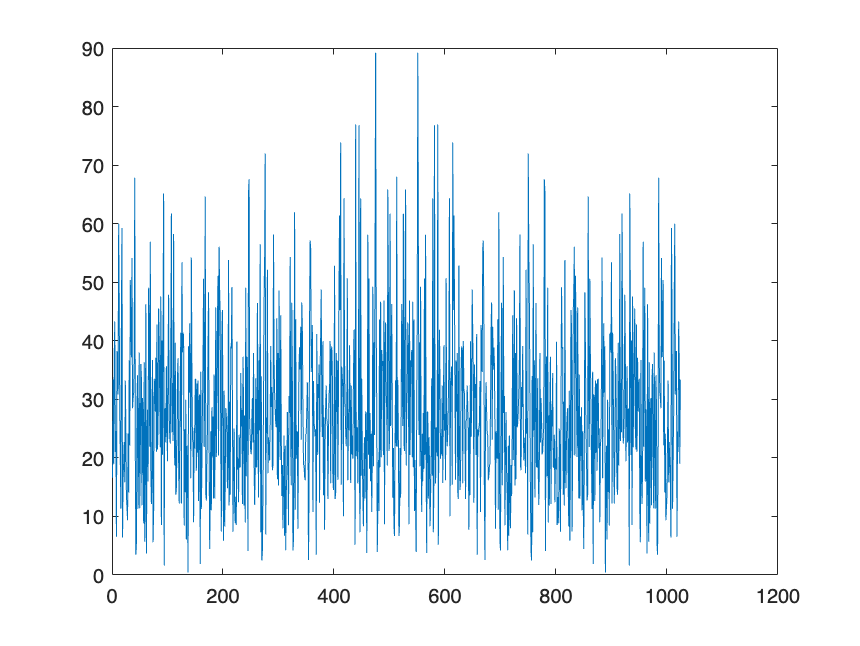


x = s + w;

% rn = w.*v;
v0 = v;
w0 = w;

% find the cross correlation
rsx = zeros(3, 1); % Initialize rsx as a vector of zeros
for n = 5:length(v)
    rsx(1) = rsx(1) + v(n)' * w(n);
    rsx(2) = rsx(2) + v(n-1)' * w(n);
    rsx(3) = rsx(3) + v(n-2)' * w(n);
end
rsx = rsx / (length(v)-2);

% find the autocorrelation
v3 = v0(1:end-2);
v2 = v0(2:end-1);
v1 = v0(3:end);

X = [v1; v2; v3;]; % Concatenate the autocorrelation variables

Rxx = X * X' / length(v3);

hW = rsx' * inv(Rxx);

% apply to colored noise to make it white again
w_hat = filter(hW, 1, v);

% check to see the whitening
figure; plot(abs(fftshift(fft(w_hat, 2^10))))

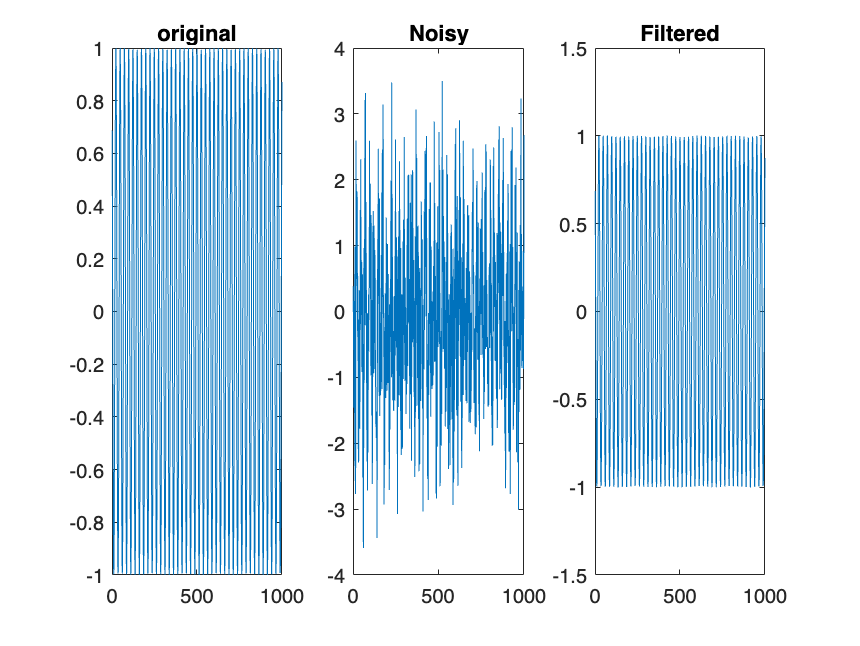


norm(w - w_hat); % to minimize
x_hat = x - w_hat;

subplot(131); plot(s); title('original');
subplot(132); plot(x); title('Noisy');
subplot(133); plot(x_hat); title('Filtered');


rms_noise_3 = norm(x - s)

rms_noise_3 = 31.7167

rms_filtered_noise_3 = norm(x - s - w_hat)

rms_filtered_noise_3 = 0.0323

#### Φίλτρο Μήκους 4

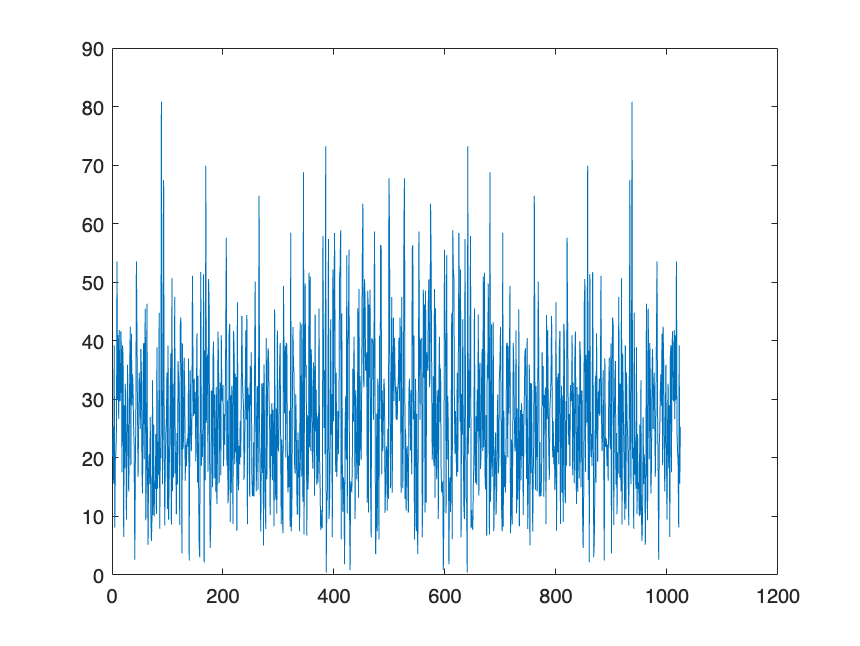

n = 0:1000;
phi = rand(1)*2*pi;
s = sin(0.25*n+phi);

w = randn(1,length(n));
v = filter(1,[1,-0.6],w); % colored noise

% check
figure; plot(abs(fftshift(fft(w,2^10))))

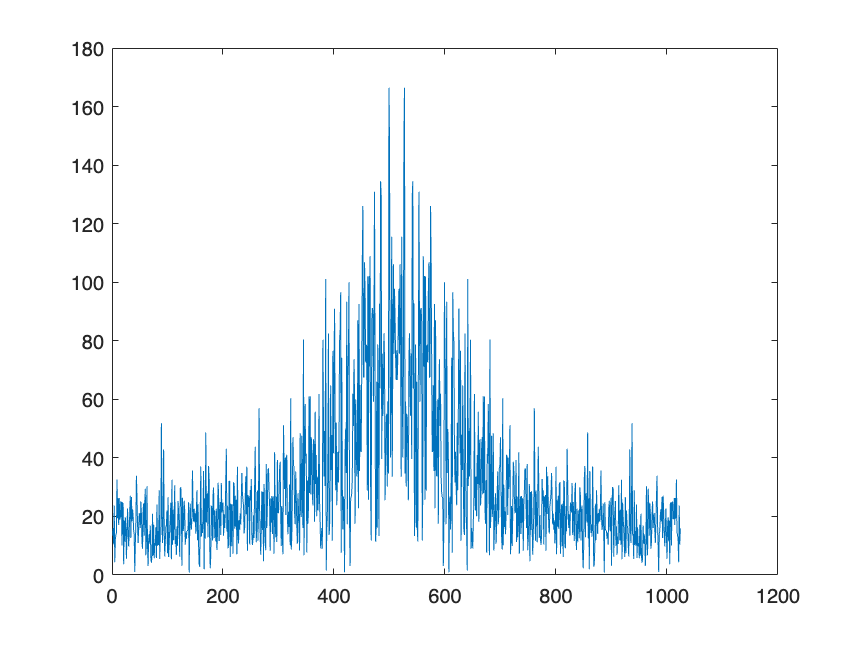

figure; plot(abs(fftshift(fft(v,2^10))))

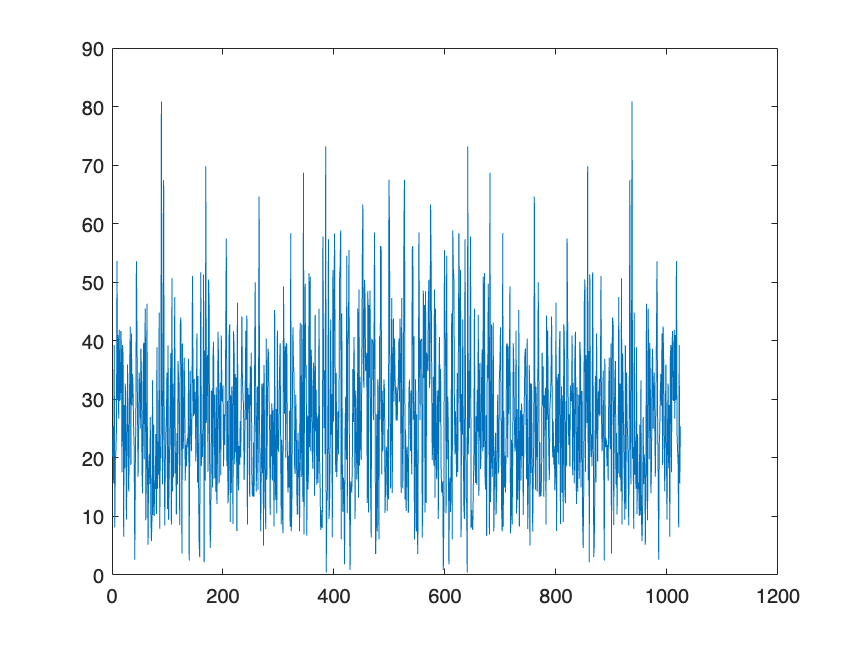


x = s + w;

% rn = w.*v;
v0 = v;
w0 = w;

% find the cross correlation
rsx = zeros(4, 1); % Initialize rsx as a vector of zeros
for n = 5:length(v)
    rsx(1) = rsx(1) + v(n)' * w(n);
    rsx(2) = rsx(2) + v(n-1)' * w(n);
    rsx(3) = rsx(3) + v(n-2)' * w(n);
    rsx(4) = rsx(4) + v(n-3)' * w(n);
end
rsx = rsx / (length(v)-3);

% find the autocorrelation

v4 = v0(1:end-3);
v3 = v0(2:end-2);
v2 = v0(3:end-1);
v1 = v0(4:end);

X = [v1; v2; v3; v4;]; % Concatenate the autocorrelation variables

Rxx = X * X' / length(v4);

hW = rsx' * inv(Rxx);

% apply to colored noise to make it white again
w_hat = filter(hW, 1, v);

% check to see the whitening
figure; plot(abs(fftshift(fft(w_hat, 2^10))))

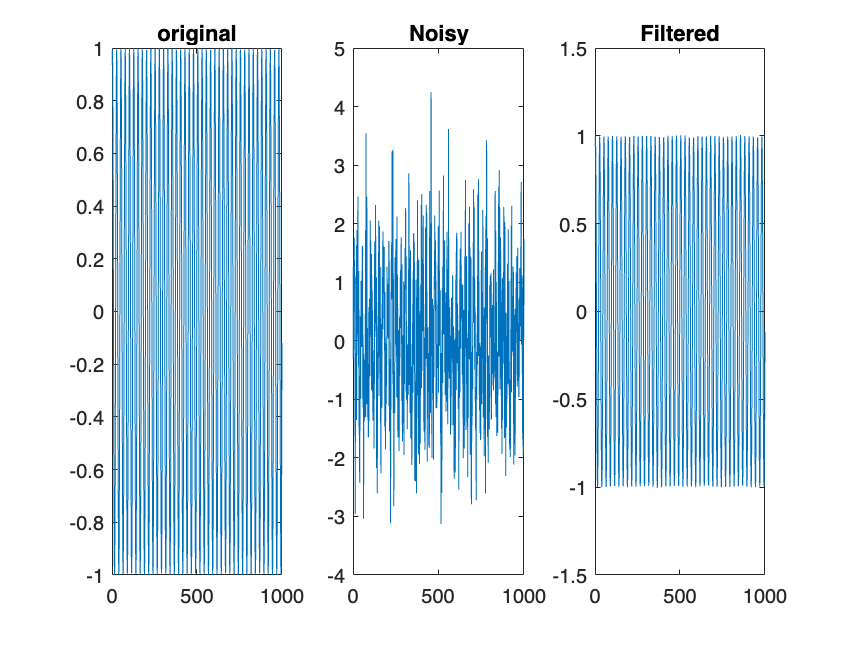


norm(w - w_hat); % to minimize
x_hat = x - w_hat;

subplot(131); plot(s); title('original');
subplot(132); plot(x); title('Noisy');
subplot(133); plot(x_hat); title('Filtered');


rms_noise_4 = norm(x - s)

rms_noise_4 = 30.4522

rms_filtered_noise_4 = norm(x - s - w_hat)

rms_filtered_noise_4 = 0.0636

#### Φίλτρο Μήκους 5

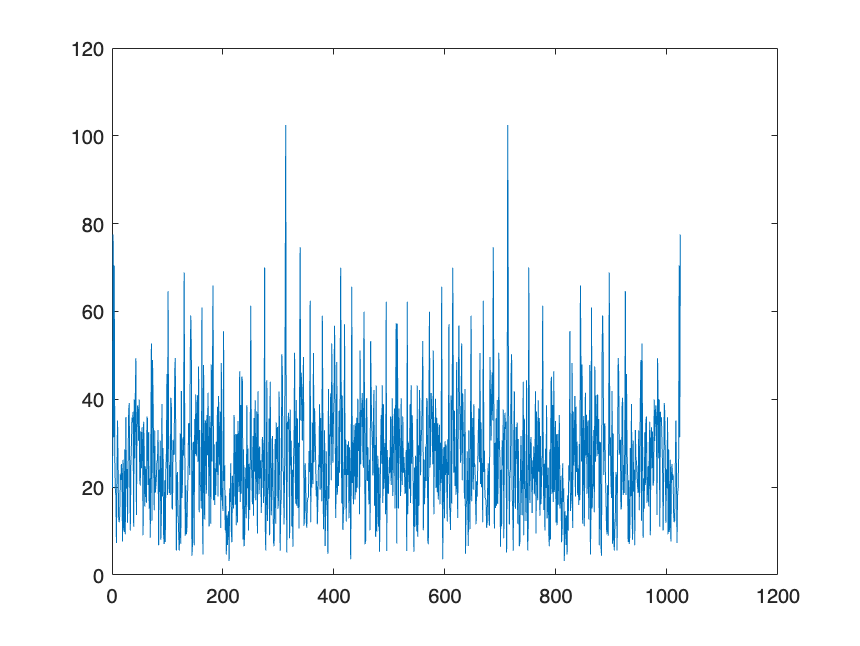

n = 0:1000;
phi = rand(1)*2*pi;
s = sin(0.25*n+phi);

w = randn(1,length(n));
v = filter(1,[1,-0.6],w); % colored noise

% check
figure; plot(abs(fftshift(fft(w,2^10))))

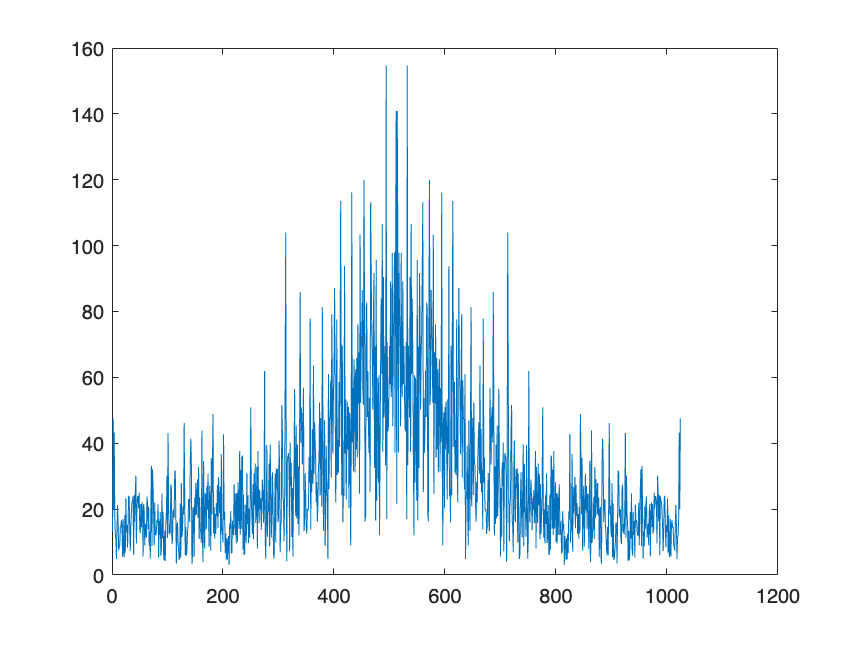

figure; plot(abs(fftshift(fft(v,2^10))))


x = s + w;

% rn = w.*v;
v0 = v;
w0 = w;

% find the cross correlation
rsx = zeros(5, 1); % Initialize rsx as a vector of zeros
for n = 5:length(v)
    rsx(1) = rsx(1) + v(n)' * w(n);
    rsx(2) = rsx(2) + v(n-1)' * w(n);
    rsx(3) = rsx(3) + v(n-2)' * w(n);
    rsx(4) = rsx(4) + v(n-3)' * w(n);
    rsx(5) = rsx(5) + v(n-4)' * w(n);
end
rsx = rsx / (length(v)-4);

% find the autocorrelation
v5 = v0(1:end-4);
v4 = v0(2:end-3);
v3 = v0(3:end-2);
v2 = v0(4:end-1);
v1 = v0(5:end);

X = [v1; v2; v3; v4; v5]; % Concatenate the autocorrelation variables

Rxx = X * X' / length(v5);

hW = rsx' * inv(Rxx);

% apply to colored noise to make it white again
w_hat = filter(hW, 1, v);

% check to see the whitening
figure; plot(abs(fftshift(fft(w_hat, 2^10))))

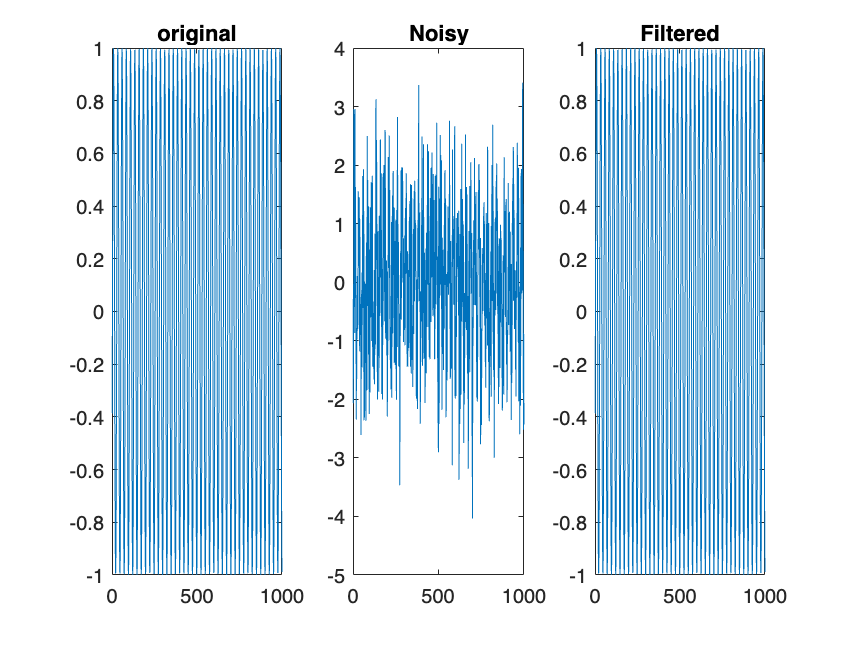


norm(w - w_hat); % to minimize
x_hat = x - w_hat;

subplot(131); plot(s); title('original');
subplot(132); plot(x); title('Noisy');
subplot(133); plot(x_hat); title('Filtered');


rms_noise_5 = norm(x - s)

rms_noise_5 = 30.1191

rms_filtered_noise_5 = norm(x - s - w_hat)

rms_filtered_noise_5 = 1.0680e-14

#### Φίλτρο Μήκους 6

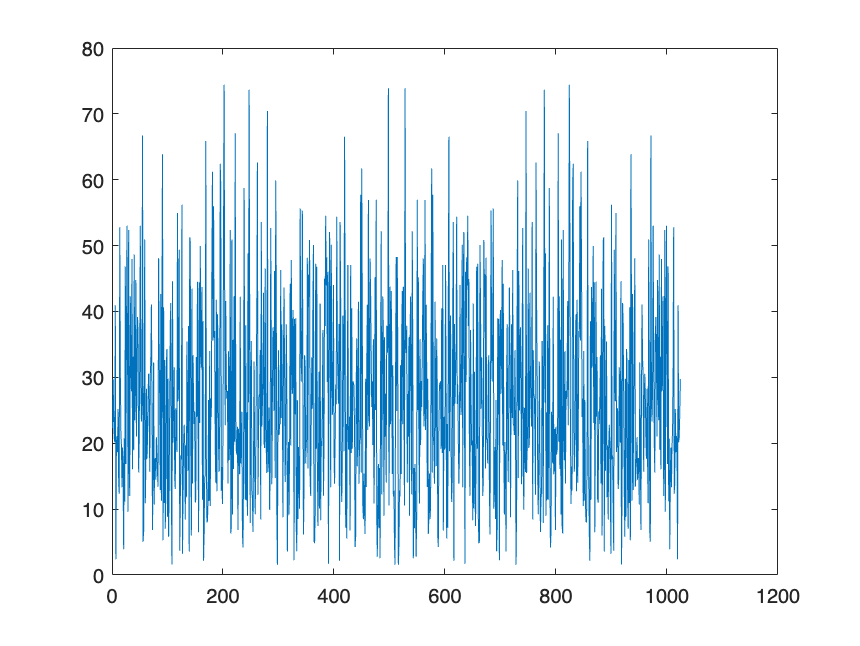

n = 0:1000;
phi = rand(1)*2*pi;
s = sin(0.25*n+phi);

w = randn(1,length(n));
v = filter(1,[1,-0.6],w); % colored noise

% check
figure; plot(abs(fftshift(fft(w,2^10))))

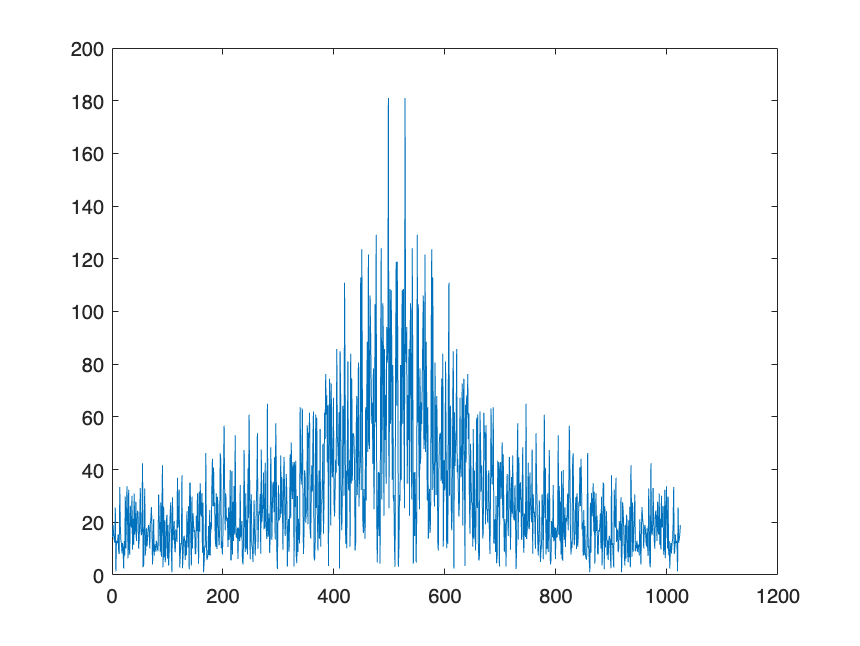

figure; plot(abs(fftshift(fft(v,2^10))))


x = s + w;

% rn = w.*v;
v0 = v;
w0 = w;

% find the cross correlation
rsx = zeros(6, 1); % Initialize rsx as a vector of zeros
for n = 6:length(v)
    rsx(1) = rsx(1) + v(n)' * w(n);
    rsx(2) = rsx(2) + v(n-1)' * w(n);
    rsx(3) = rsx(3) + v(n-2)' * w(n);
    rsx(4) = rsx(4) + v(n-3)' * w(n);
    rsx(5) = rsx(5) + v(n-4)' * w(n);
    rsx(6) = rsx(6) + v(n-5)' * w(n);
end
rsx = rsx / (length(v)-5);

% find the autocorrelation
v6 = v0(1:end-5);
v5 = v0(2:end-4);
v4 = v0(3:end-3);
v3 = v0(4:end-2);
v2 = v0(5:end-1);
v1 = v0(6:end);

X = [v1; v2; v3; v4; v5; v6]; % Concatenate the autocorrelation variables

Rxx = X * X' / length(v6);

hW = rsx' * inv(Rxx);

% apply to colored noise to make it white again
w_hat = filter(hW, 1, v);

% check to see the whitening
figure; plot(abs(fftshift(fft(w_hat, 2^10))))

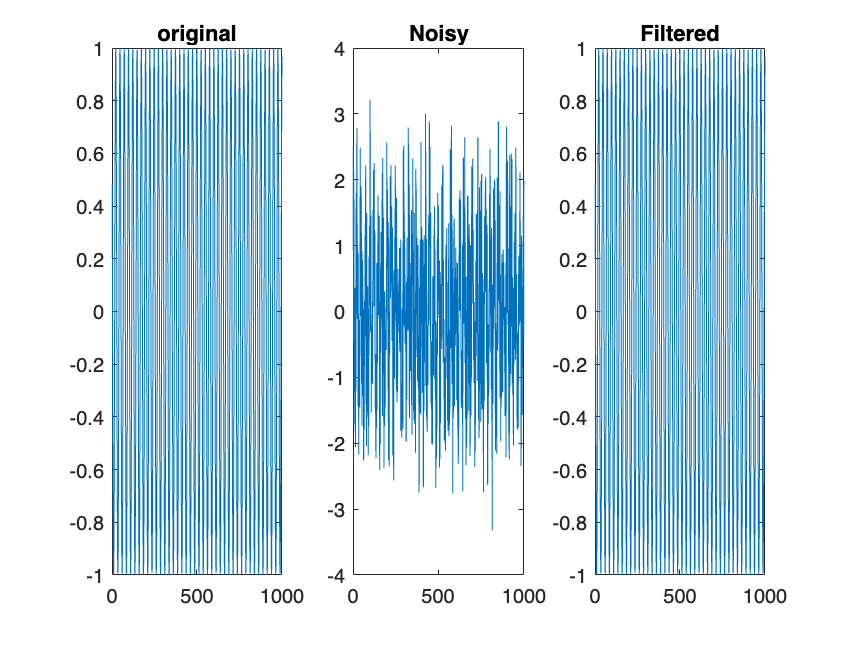


norm(w - w_hat); % to minimize
x_hat = x - w_hat;

subplot(131); plot(s); title('original');
subplot(132); plot(x); title('Noisy');
subplot(133); plot(x_hat); title('Filtered');


rms_noise_6 = norm(x - s)

rms_noise_6 = 30.7416

rms_filtered_noise_6 = norm(x - s - w_hat)

rms_filtered_noise_6 = 4.9758e-14